%Histogram Computation
im1=[127/255 127/255 0 1;127/255 0 0 1;0 127/255 0 1; 127/255 127/255 0 1]

im1 =     0.4980    0.4980         0    1.0000
    0.4980         0         0    1.0000
         0    0.4980         0    1.0000
    0.4980    0.4980         0    1.0000


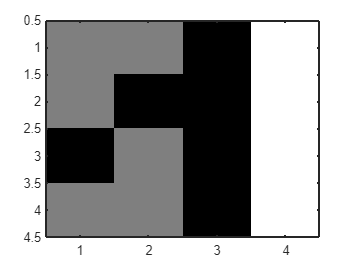

% Build the LUT to display in gray levels
r=[0 0.5 1];
g=[0 0.5 1];
b=[0 0.5 1];
map=[r' g' b'];
imagesc(im1);
colormap(map) ;

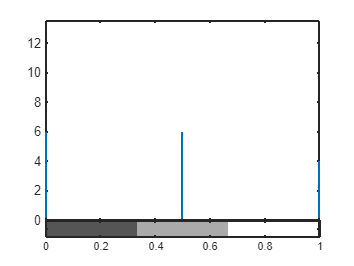

% Plot the image histogram
figure
imhist(im1,3) ;

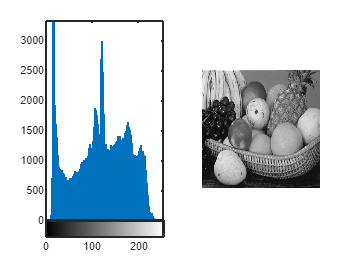

I = imread('FRUIT_LUMI.BMP') ;
J = imread('MANDRILL_LUMI.BMP') ;
figure
subplot(121)
imhist(I)
 subplot (122)
imshow(I)

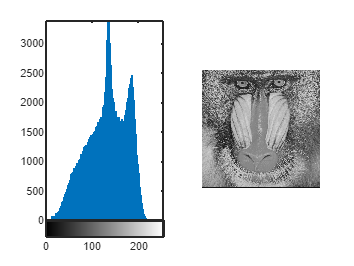

figure
 subplot(121)
imhist(J); 
 subplot(122)
imshow(J)

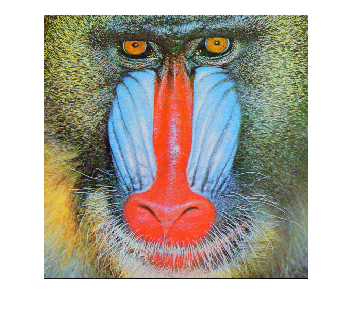

I = imread('MANDRILL.BMP') ;
figure
imshow (I)

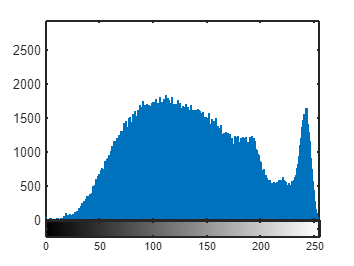

figure
imhist(I(:,:,1)); % first plane: Red

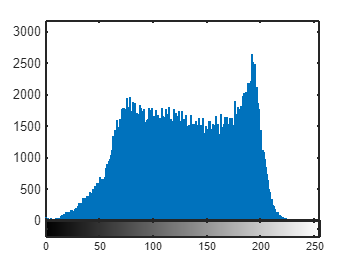

figure
imhist(I(:,:,2)); % second plane: Green

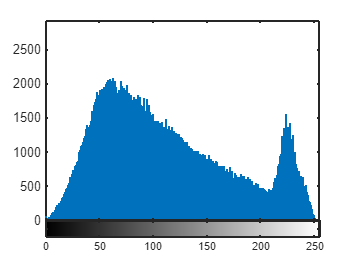

figure
imhist(I(:,:,3)); % third plane: Blue

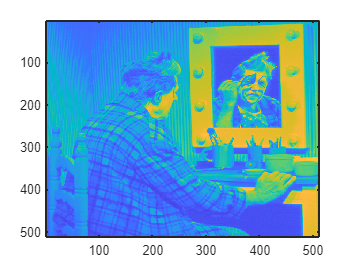

%HistogramEqu
r=0:1/255:1; g=r; b=r;
% Histogram equalization
I=imread('CLOWN_LUMI.BMP') ;
image(I)

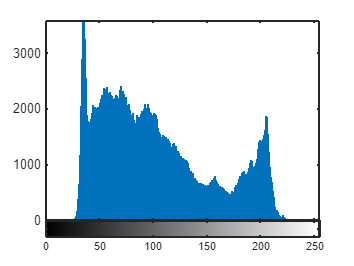

figure
%imshow (I)
colormap([r' g' b'])
figure
imhist(I);

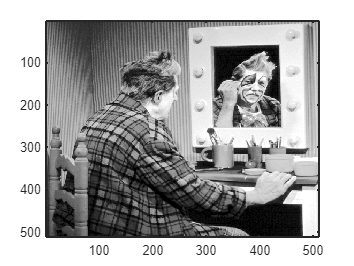

J=histeq(I);
figure
image(J)
colormap([r' g' b'])

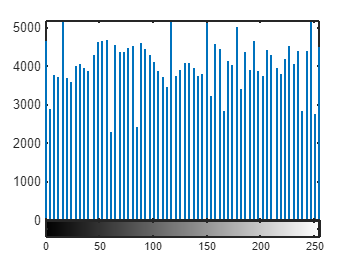

figure
imhist(J)

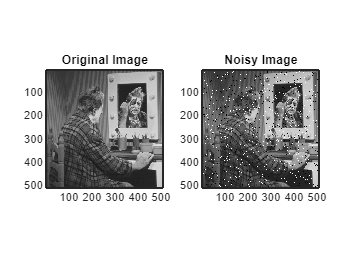

%Non linear - median 
I=imread('CLOWN_LUMI.BMP') ; % to read the grayscale image
IB = imnoise(I,'salt & pepper'); % to create the noisy image
figure(1)
subplot(1,2,1)
subimage(I)
title('Original Image')
subplot(1,2,2)
subimage(IB)
title('Noisy Image')

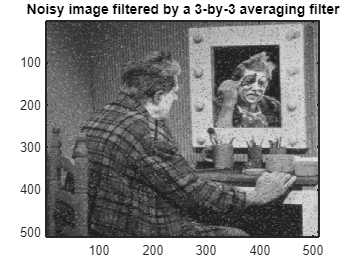


% Averaging filter
N = ones(3)/9 ; % convolution kernel
If1 = imfilter(IB,N) ;
figure(2)
image(If1)
title('Noisy image filtered by a 3-by-3 averaging filter')
v=0:1/255:1; colormap([v' v' v']); % LUT for displaying in gray level

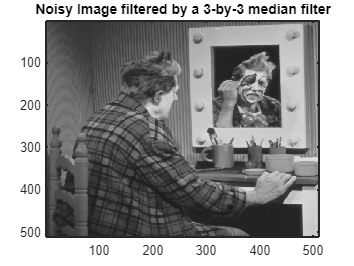



% Median filtering
If2 = medfilt2(IB,[3 3]) ; % 3-by-3 median filtering
figure(3)
image(If2)
title('Noisy Image filtered by a 3-by-3 median filter')
v=0:1/255:1; colormap([v' v' v']); % LUT for displaying in gray levels

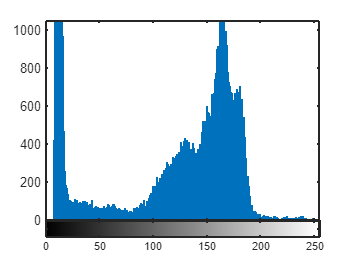

%Img seg
%% Thershold - Manual selection

I = imread('cameraman.tif');
figure,
imhist(I);

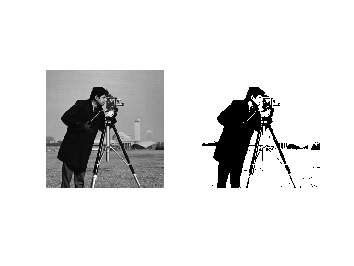

figure,
subplot(1,2,1); imshow(I);
subplot(1,2,2); im2bw(I,80/255);

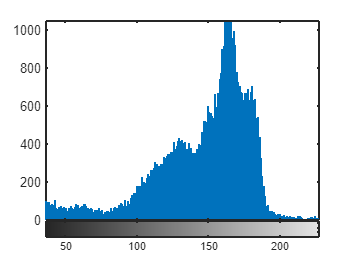




%% Otsu method


clear all


I = imread('cameraman.tif');
figure,
imhist(I);

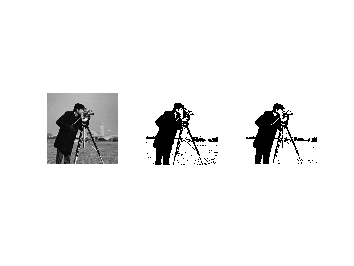

figure,
subplot(1,3,1); imshow(I);
subplot(1,3,2); im2bw(I,100/255);
thresh = graythresh(I); % Find threshold value using Otsu method
subplot(1,3,3); im2bw(I,thresh);





%% Thershold - Manual selection


clear all


I = imread('cameraman.tif');
%figure,
%imhist(I);
%figure,
%subplot(2,2,1); imshow(I);
%subplot(2,2,2); im2bw(I,100/255);

[counts,X] = imhist(I); %Calculate histogram of the image
P = polyfit(X,counts,6); % Approximate histogram wiht polynomial function

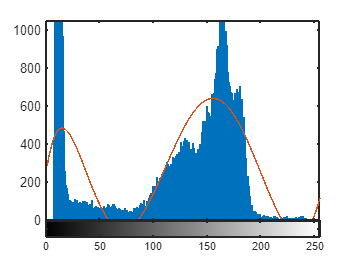

Y = polyval(P,X); %Calculate value of hte polynomial function for each X

figure,
imhist(I);
hold on
plot(Y);
hold off

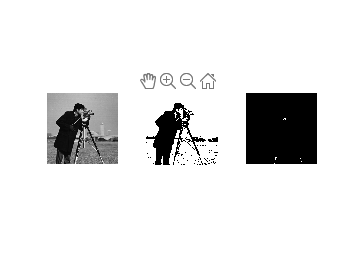


%Determine threshold value by determining minimum value of polynomial 
% funcion
[V,ind] = sort(abs(diff(Y)));
thresh = ind(3)./255;

figure,
subplot(1,3,1); imshow(I);
subplot(1,3,2); im2bw(I,100/255);
subplot(1,3,3); im2bw(I,thresh);